## Tutorial 6, problem 2a-c)

clc; clear all; close all;

J_m = 0.004; % kg*m^2
J_eff = J_m;

U_a_max = 12; % V
R_a = 1.1; % Ohm
K_m = 0.2; % Nm/A
% L is neglected

K_sys = 0.9; % Steady state speed

% a)
syms kp ksys km
eq = ksys == kp/(kp+km) % Equation 7.3 from the notes

$$eq = \mathrm{ksys}=\frac{\mathrm{kp}}{\mathrm{km}+\mathrm{kp}}$$

kp = solve(eq,kp)

$$kp = -\frac{\mathrm{km}\,\mathrm{ksys}}{\mathrm{ksys}-1}$$


K_p = -(K_m*K_sys/(K_sys-1))

K_p =                        1.8



% b)
tau_sys = R_a * J_eff/(K_m*(K_p+K_m))

tau_sys =                      0.011



% c)
thetaDot_ref = 40; % rad/s
simTime = 0.25; % s

theta = 0;
thetaDot = 0;

t = 0;
dt = 10^-3;
idx = 1;

while(t <= simTime)
    % Calculations
    thetaDot_err = thetaDot_ref - thetaDot;

    U_a = K_p * thetaDot_err;
    if(U_a >= U_a_max)
        U_a = U_a_max;
    end

    i_a = (U_a-K_m*thetaDot)/R_a; % Equation 5.19 from notes

    tau_m = K_m*i_a; % ??

    thetaDotDot = tau_m/J_m; % ??
    % Logging
    time_plot(idx) = t;
    thetaDot_plot(idx) = thetaDot;

    % Time Integrate
    thetaDot = thetaDot + thetaDotDot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;


end

plot(time_plot, thetaDot_plot, 'LineWidth', 2)
legend("$\dot{\theta}$", 'Interpreter','latex')
grid

## Tutorial 6, problem 2d)

clc; clear all; close all;

J_m = 0.004; % kg*m^2
J_eff = J_m;

U_a_max = 12; % V
R_a = 1.1; % Ohm
K_m = 0.2; % Nm/A
L_a = 0.015; % H
i = 0; % Initial current through inductor

K_sys = 0.9; % Steady state speed

K_p = -(K_m*K_sys/(K_sys-1))

K_p =                        1.8



tau_sys = R_a * J_eff/(K_m*(K_p+K_m))

tau_sys =                      0.011


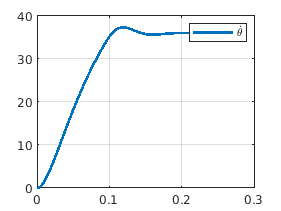


thetaDot_ref = 40; % rad/s
simTime = 0.25; % s

theta = 0;
thetaDot = 0;

t = 0;
dt = 10^-3;
idx = 1;

while(t <= simTime)
    % Calculations
    thetaDot_err = thetaDot_ref - thetaDot;

    U_a = K_p * thetaDot_err;
    if(U_a >= U_a_max)
        U_a = U_a_max;
    end

    iDot = 1/L_a * (U_a - i * R_a - K_m * thetaDot); % Equation 5.18 from notes

    M_m = K_m*i; % Equation 5.16 from notes

    thetaDotDot = M_m/J_eff; % Equation 5.15 from notes
    % Logging
    time_plot(idx) = t;
    thetaDot_plot(idx) = thetaDot;

    % Time integrate
    thetaDot = thetaDot + thetaDotDot * dt;
    i = i + iDot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;


end

plot(time_plot, thetaDot_plot, 'LineWidth', 2)
legend("$\dot{\theta}$", 'Interpreter','latex')
grid